# **Κεφάλαιο 3: Μετασχηματισμοί Δεδομένων**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, έχουν προσαρμοστεί από παραδείγματα που βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## Ανάλυση σε Κύριες Συνιστώσες

### Παράδειγμα 1

Δημιουργήστε ένα σύνολο $X_1$ που αποτελείται από $N=500$ διδιάστατα διανύσματα που ακολουθούν Gaussian κατανομή μηδενικής μέσης τιμής και μητρώου συνδιασποράς


$$S_2=\left[ \matrix {0.3 & 0.2 \cr 0.2 & 1.0}
\right]$$


Εφαρμόστε PCA στο $X_1$, δηλαδή υπολογίστε τις ιδιοτιμές / ιδιοδιανύσματα της εκτίμησης $\hat{S_1}$ του $S_1$, η οποία προκύπτει από τα διανύσματα του $X_1$. Λαμβάνοντας υπόψιν ότι η $i-$οστή ιδιοτιμή "εξηγεί" τη διασπορά στην διεύθυνση του $i-$οστού ιδιοδιανύσματος του $\hat{S_1}$, υπολογίστε το ποσοστό της διασποράς που οφείλεται σε κάθε μια συνιστώσα, ως τον λόγο 

1. Δημιουργήστε και σχεδιάστε ένα σύνολο δεδομένων $X_1$ (σύνολο εκπαίδευσης) που περιέχει $60$ σημεία της κλάσης $+1$ ( $20$ από κάθε κατανομή) και $80$ σημεία της κλάσης $-1$ (και πάλι $20$ σημεία από κάθε κατανομή). Χρησιμοποιήστε την ίδια συνταγή για να παράγετε το σύνολο $X_2$ (σύνολο δοκιμής).

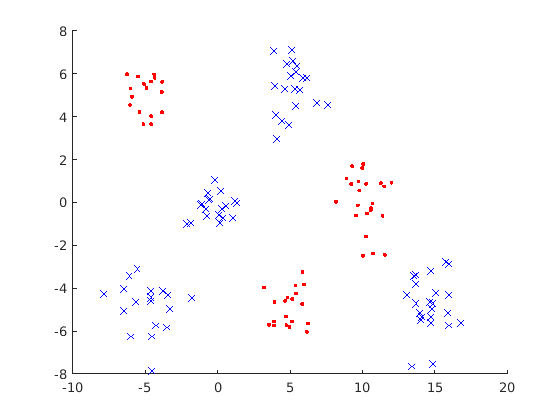

close('all');
clear;

randn('seed',0);
% 1. Generate data set X1 
l=2; %Dimensionality
m1=[-5 5; 5 -5; 10 0]'; % centroids
m2=[-5 -5; 0 0; 5 5; 15 -5]';
[l,c1]=size(m1); %no of gaussians per class
[l,c2]=size(m2);

P1=ones(1,c1)/c1; % weights of the mixture model
P2=ones(1,c2)/c2;
s=1; % variance

% Generate the training data from the first class
N1=60; %Number of first class data points
for i=1:c1
    S1(:,:,i)=s*eye(l);
end
sed=0; %Random generator seed
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Generate the training data from the second class
N2=80; %Number of second class data points
for i=1:c2
    S2(:,:,i)=s*eye(l);
end
sed=0; 
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);

% Form X1
X1=[class1_X  class2_X]; %Data vectors
y1=[ones(1,N1) -ones(1,N2)]; %Class labels
figure(1), hold on
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==-1),X1(2,y1==-1),'bx')


% Generate test set X2

% Data of the first class
sed=100; %Random generator seed. This time we set this value to 100
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Data of the second class
sed=100; %Random generator seed
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);

%Production of the unified data set
X2=[class1_X class2_X]; %Data vectors
y2=[ones(1,N1) -ones(1,N2)]; %Class labels

2. Με βάση το $X_1$, εκπαιδεύστε ένα νευρωνικό δίκτυο ακτινωτής συνάρτησης βάσης (RBF), με $2, 5, 10, 20, 50$ κόμβους στο κρυφό επίπεδο. Όλοι οι κόμβοι του κρυφού επιπέδου χρησιμοποιούν την Gaussian ως συνάρτηση ενεργοποίησης ενώ ο κόμβος εξόδου χρησιμοποιεί τη γραμμική συνάρτηση ενεργοποίησης. Τρέξτε τον τυπικό αλγόριθμο εκπαίδευσης επιλέγοντας ως διασπορά (spread) των RBF συναρτήσεων ίση με $1$, και υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής (με βάση τα $X_1$ και $X_2$ αντίστοιχα) και σχεδιάστε τα σημεία εκπαίδευσης και τις περιοχές απόφασης που σχηματίζει το δίκτυο. Να γίνει επίσης η γραφική παράσταση του σφάλματος εκπαίδευσης ως προς το πλήθος των επαναλήψεων.

NEWRB, neurons = 0, MSE = 0.979592
NEWRB, neurons = 50, MSE = 0.00598728
NEWRB, neurons = 100, MSE = 5.48503e-05


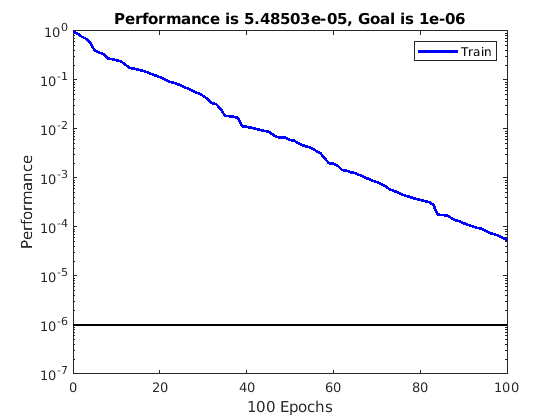

rand('seed',100) 
randn('seed',100)
min_error = 1e-6; %this is the minimum error for the training
k=500; %number of hidden layer nodes
spread = 1; %the spread of the RBF network
net = newrb(X1, y1, min_error, spread, k);

% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)

pe_train = 0

pe_test=NN_evaluation(net,X2,y2)

pe_test = 0.0143

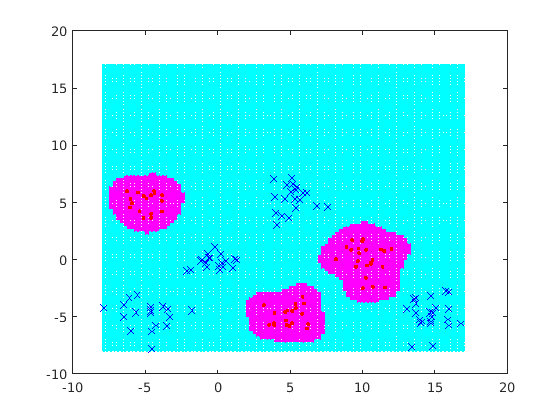


% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];
fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution
plot_NN_reg(net,bou,resolu,fig_num); % plot decision region
figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')

3. Να επαναληφθεί το βήμα $2$, θέτοντας την διασπορά ίση με $0.1$

NEWRB, neurons = 0, MSE = 0.979592
NEWRB, neurons = 50, MSE = 0.0055398
NEWRB, neurons = 100, MSE = 0.00128484


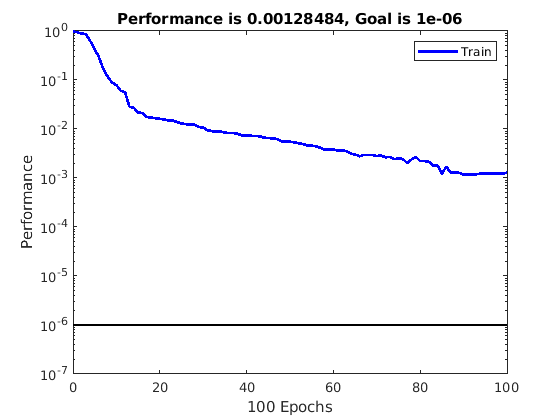

rand('seed',100) 
randn('seed',100)
min_error = 1e-6; %this is the minimum error for the training
k=500; %number of hidden layer nodes
spread = 10; %the spread of the RBF network
net = newrb(X1, y1, min_error, spread, k);


% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)

pe_train = 0

pe_test=NN_evaluation(net,X2,y2)

pe_test = 0

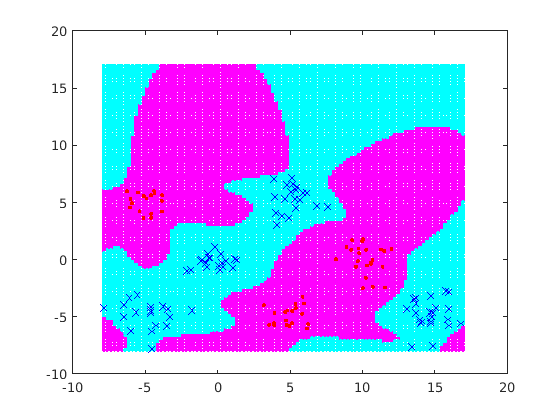


% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];
fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution
plot_NN_reg(net,bou,resolu,fig_num); % plot decision region
figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')

### Άσκηση 1

Να επαναλάβετε το προηγούμενο παράδειγμα αλλά αυτή την φορά το μητρώο συνδιασποράς των Gaussian κατανομών να είναι ίσο με $\sigma^2I$ όπου $\sigma^2=4$ και $I$ είναι ο ταυτοτικός πίνακας $2\times 2$.

Σημειώστε ότι σε αυτή την περίπτωση, τα σημεία κάθε κλάσης έχουν μεγαλύτερη διασπορά και κατά συνέπεια οι κλάσεις δεν διαχωρίζονται με τόσο εμφανή τρόπο, όπως στο Παράδειγμα. Άρα θα πρέπει να τροποποιήσουμε αναλόγως την τιμή της διασποράς των συναρτήσεων RBF. Ποιες τιμές δίνουν τα καλύτερα αποτελέσματα;

### Παράδειγμα 2

Έστω δισδιάστατο πρόβλημα ταξινόμησης δύο κλάσεων. Τα σημεία της πρώτης (δεύτερης) κλάσης συμβολίζονται με $+1(-1)$ και πηγάζουν από τέσσερις (πέντε) ισοπίθανες Gaussian κατανομές με μέσες τιμές $[-10,0]^T,[0,-10]^T, [10,0]^T ([-10,-10]^T, [0,0]^T, [10,-10]^T, [-10,10]^T, [10,10]^T)$.  Το μητρώο συνδιασποράς κάθε κατανομής είναι ίσο με $\sigma^2I$ όπου $\sigma^2=4$ και $I$ είναι ο ταυτοτικός πίνακας $2\times 2$.

1. Δημιουργήστε και σχεδιάστε ένα σύνολο δεδομένων $X_1$ (σύνολο εκπαίδευσης) που περιέχει $80$ σημεία της κλάσης $+1$ ( $20$ από κάθε κατανομή) και $100$ σημεία της κλάσης $-1$ (και πάλι $20$ σημεία από κάθε κατανομή). Χρησιμοποιήστε την ίδια συνταγή για να παράγετε το σύνολο $X_2$ (σύνολο δοκιμής).

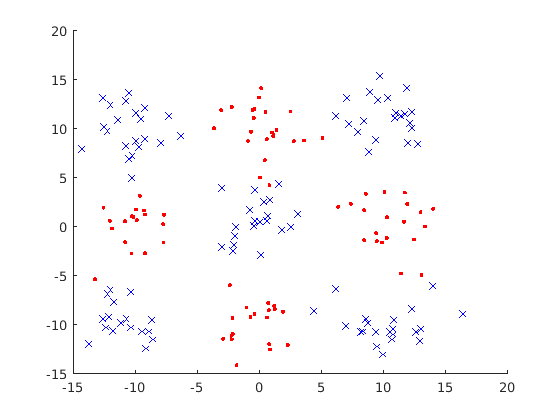

close('all');
clear;

randn('seed',0);
% 1. Generate the training data set (X1)
l=2; %Dimensionality
m1=[-10 0; 0 -10; 10 0; 0 10]'; % centroids of the first class
m2=[-10 -10; 0 0; 10 -10; -10 10;10 10]'; % centroids of the second class 
[l,c1]=size(m1); 
[l,c2]=size(m2);

P1=ones(1,c1)/c1;
P2=ones(1,c2)/c2;

% Generate data for the first class of the training set
N1=80; % Approximately 20 for each one of the four clusters
s=4;
for i=1:c1
    S1(:,:,i)=s*eye(l);
end
sed=0; %Random generator seed
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Generate data for the second class of X1
N2=100; % Approximately 20 for each one of the four clusters
for i=1:c2
    S2(:,:,i)=s*eye(l);
end
sed=0; %Random generator seed
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);

% Merge the data of the two classes to form the training set
X1=[class1_X  class2_X]; 
y1=[ones(1,N1) -ones(1,N2)]; 
figure(1), hold on
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==-1),X1(2,y1==-1),'bx')

% 1. Generate test set (X2)
% Generate data for the first class of X2
sed=100; 
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Generate data for the second class of X2

sed=100; 
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);

% Form X2
X2=[class1_X  class2_X]; 
y2=[ones(1,N1) -ones(1,N2)]; 

2. Με βάση το $X_1$, εκπαιδεύστε ένα νευρωνικό δίκτυο ακτινωτής συνάρτησης βάσης (RBF), με $2, 5, 10, 20, 50,100$ κόμβους στο κρυφό επίπεδο. Όλοι οι κόμβοι του κρυφού επιπέδου χρησιμοποιούν την Gaussian ως συνάρτηση ενεργοποίησης ενώ ο κόμβος εξόδου χρησιμοποιεί τη γραμμική συνάρτηση ενεργοποίησης. Τρέξτε τον τυπικό αλγόριθμο εκπαίδευσης επιλέγοντας ως διασπορά (spread) των RBF συναρτήσεων ίση με $2$, και υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής (με βάση τα $X_1$ και $X_2$ αντίστοιχα) και σχεδιάστε τα σημεία εκπαίδευσης και τις περιοχές απόφασης που σχηματίζει το δίκτυο. Να γίνει επίσης η γραφική παράσταση του σφάλματος εκπαίδευσης ως προς το πλήθος των επαναλήψεων. Να εξαχθούν συμπεράσματα.

NEWRB, neurons = 0, MSE = 0.987654
NEWRB, neurons = 50, MSE = 0.210217
NEWRB, neurons = 100, MSE = 0.0274155
NEWRB, neurons = 150, MSE = 0.000254528


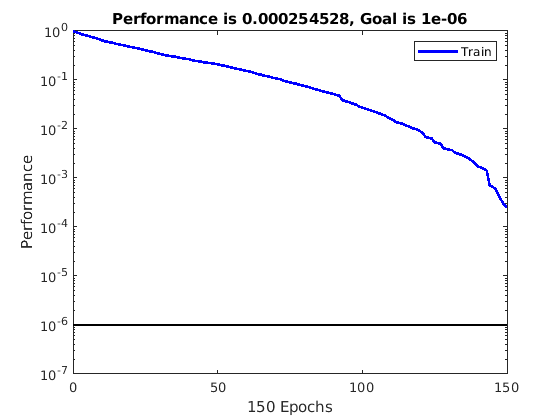

rand('seed',100) 
randn('seed',100)
min_error = 1e-6; %this is the minimum error for the training
k=500; %number of hidden layer nodes
spread = 1; %the spread of the RBF network
net = newrb(X1, y1, min_error, spread, k);
% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)
pe_test=NN_evaluation(net,X2,y2)

% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];

fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution

pe_train = 0

plot_NN_reg(net,bou,resolu,fig_num); % plot decision region

pe_test = 0.0500

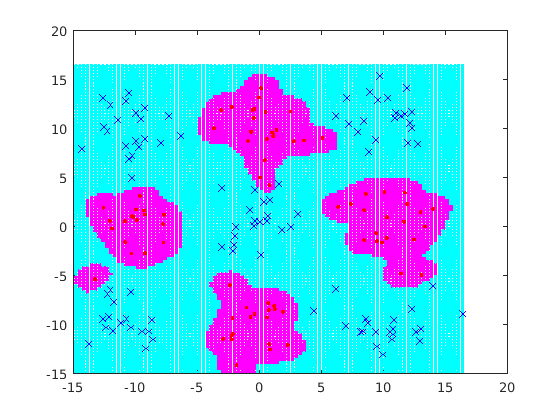

figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')